Here we just use that the equation of the circle must be


$$x^2+y^2+ax+by+c=0$$


and so we solve $\left\lbrack \begin{array}{ccc}
x & y & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
a\\
b\\
c
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
-x^2 -y^2 
\end{array}\right\rbrack$

clc;
clear;
clf;
x = [-1 0 1.1 2.4]';
y = [-2 2.4 -4 -1.6]';
A = [x y ones(4,1)];
b = -(x.^2 + y.^2);
c = A\b

c =    -1.1510
    1.2852
   -6.6823


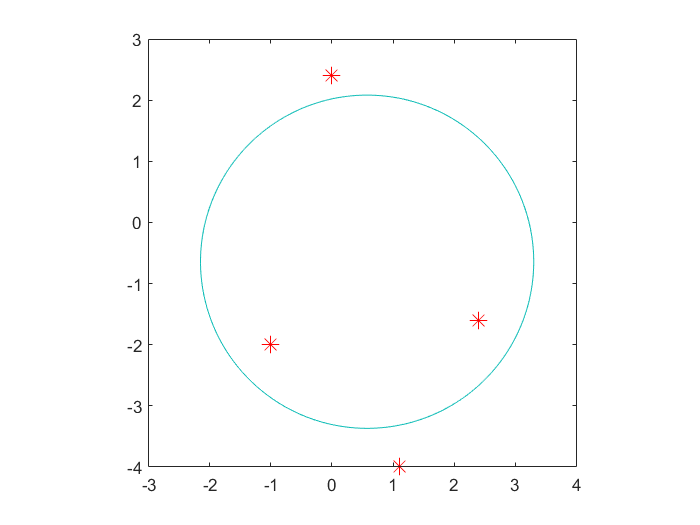

[X,Y] = meshgrid(linspace(-3,4, 100),linspace(-4, 3, 100));
Z = X.^2 + Y.^2 + c(1)*X + c(2)*Y + c(3)*ones(size(X));

contour(X,Y,Z,[0 0])
daspect([1 1 1])

hold on
plot(x,y,'r*','MarkerSize',10)

Following *Application 3* from the text we know that if our data lies on the circle


$$(x-h)^2+(y-k)^2=r^2$$


Then we can rewrite this as 


$$x^2-2xh+h^2+y^2-2ky+k^2=r^2$$


So we look for *h*, *k*, and *r* satisfying


$$h(2x)+k(2y)+(r^2-h^2+k^2)=x^2+y^2$$


So let $l=r^2-h^2-k^2$ and solve $\left\lbrack \begin{array}{ccc}
2x & 2y & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
h\\
k\\
l
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
x^2 +y^2 
\end{array}\right\rbrack$

clf;
clc;
X = [2*x 2*y ones(size(x))];
c = X\(x.^2 + y.^2)

c =     0.5755
   -0.6426
    6.6823


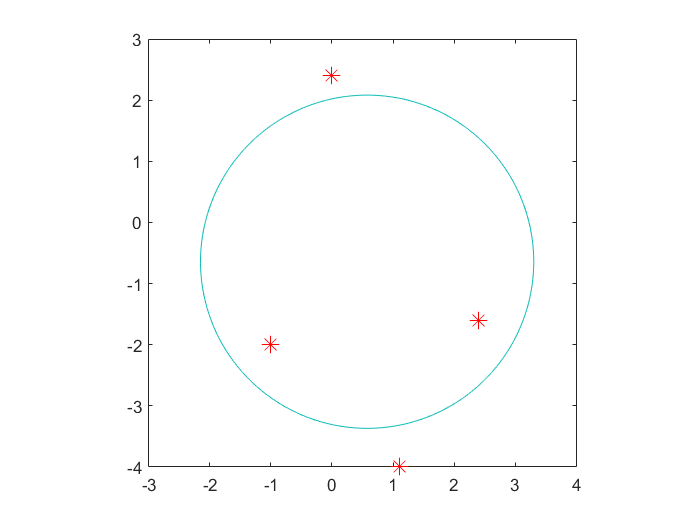

[X,Y] = meshgrid(linspace(-3,4, 100),linspace(-4, 3, 100));
Z = X.^2 + Y.^2 - c(1)*2*X - c(2)*2*Y - c(3);

figure(2);
plot(x, y, 'r*', 'MarkerSize', 10)
hold on
contour(X,Y,Z,[0  0])
daspect([1 1 1])                       